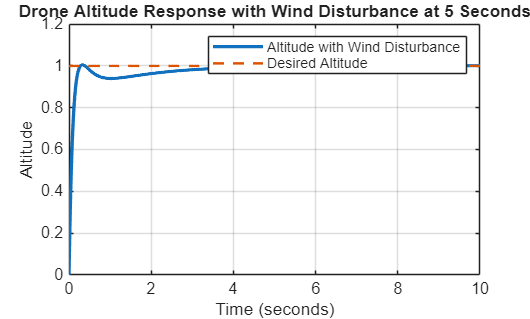

clc;
clear;
close all;

s = tf('s');

% Plant
G = 1/(s^2 + 2*s + 5);

% PID controller
Kp = 40;
Ki = 25;
Kd = 12;
C = pid(Kp, Ki, Kd);

% Closed-loop transfer function for reference input
T = feedback(C*G, 1);

% Transfer function from disturbance to output
Td = feedback(G, C);

% Time
t = 0:0.01:10;

% Desired altitude input
r = ones(size(t));

% Wind disturbance at 5 seconds
d = zeros(size(t));
d(t >= 5) = 0.2;

% Responses
y_ref = lsim(T, r, t);
y_dist = lsim(Td, d, t);

% Total altitude response
y_total = y_ref + y_dist;

% Plot
figure;
plot(t, y_total, 'LineWidth', 2);
grid on;
xlabel('Time (seconds)');
ylabel('Altitude');
title('Drone Altitude Response with Wind Disturbance at 5 Seconds');

% Add reference line
hold on;
plot(t, r, '--', 'LineWidth', 1.5);
legend('Altitude with Wind Disturbance', 'Desired Altitude');